% go to main folder of CLSM spectral analysis
cl = CLSMspectraLab({'data/raw/Al-uFCC-!2-15-1-1KDa-pH3.1-1day.nd2','data/raw/Al-uFCC-!2-15-1-1KDa-pH3.1-1day.nd2'});

Reading series #1
    ................................
Reading series #1
    ................................


% cl = CLSMspectraLab({'D:\PhD\data\inverted A1R\Yadi\20210623\IEP\ex405nm_em415-10-735nm_Al2O3-c_CD-buffer7_1.nd2','D:\PhD\data\inverted A1R\Yadi\20210623\IEP\ex405nm_em415-10-735nm_Al2O3-c_CD-buffer7_2.nd2'});
% cl = CLSMspectraLab('D:\PhD\data\inverted A1R\Yadi\20210623\IEP\ex405nm_em415-10-735nm_Al2O3-c_CD-buffer7_1.nd2');
% cl = CLSMspectraLab('C:\Users\3971627\OneDrive - Universiteit Utrecht\CFM image fo Acidity Map\FCC-Si-12-15-1-Allmirrors2.nd2')
% cl = CLSMspectraLab(true);

cl.maskFlag = false;
[cl.bgCorrection.uniformBackgroundFlag] = deal(false);
[cl.bgCorrection.c2] = deal(8);
cl = cl.computeBgCorrection;

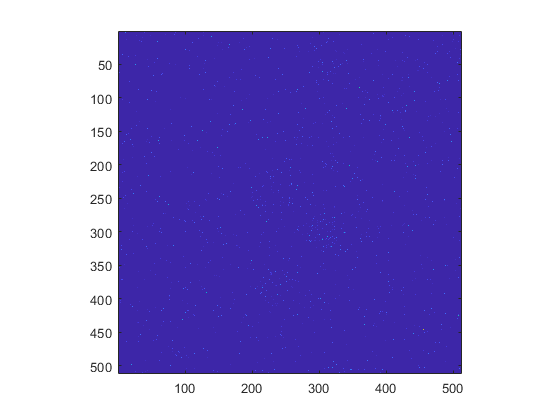

figure
cl.bgCorrection(1).plotA

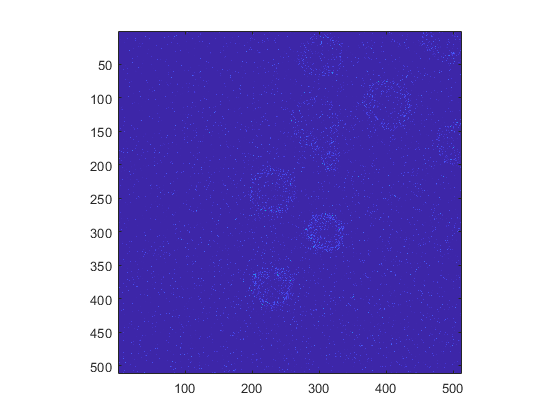

figure
cl.bgCorrection(1).plotB

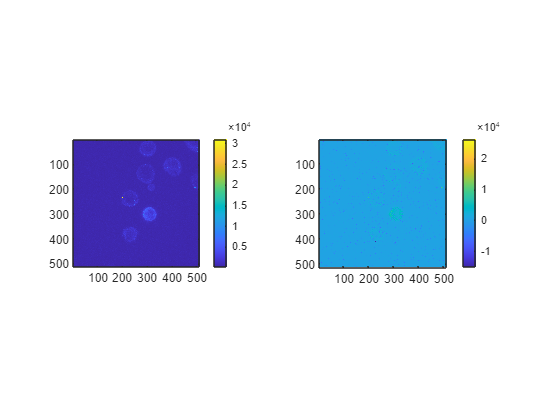

figure
subplot(1,2,1)
cl.input(1).plotImage
colorbar
subplot(1,2,2)
cl.bgCorrection(1).plotImage
colorbar

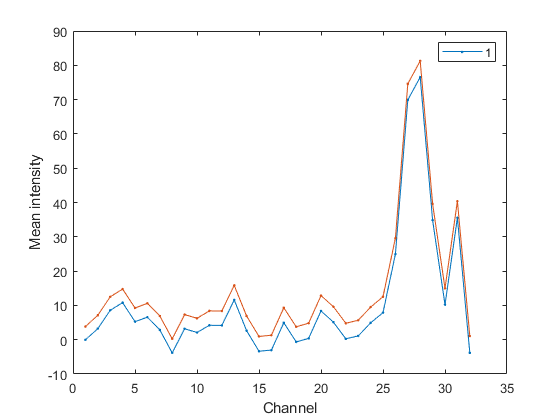

cl.bgCorrectionFlag = true;
figure
cl.plotChannels([],1)
hold on
cl(1).bgCorrectionFlag = false;
cl(1).plotChannels([],1)


cl = cl.computeMask;

Computed mask without background correction.


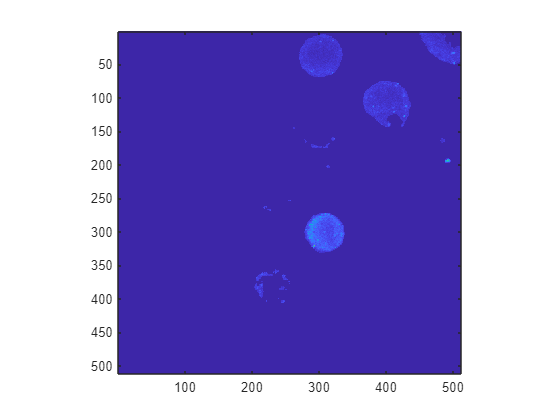

I = cl.input(1).applyMaskImageStack(cl.mask(1),'sum','x','y');
figure
I.plotImage

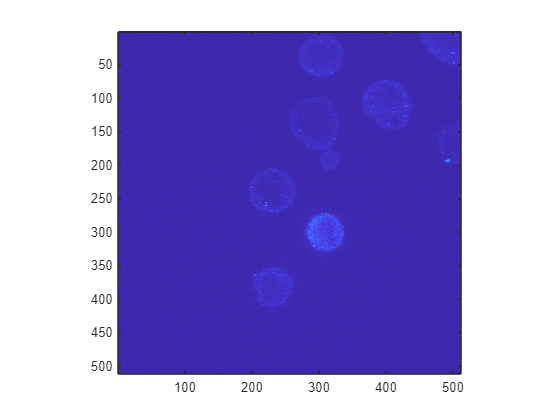

figure
cl.plotSumIntensity2D([],1,1)

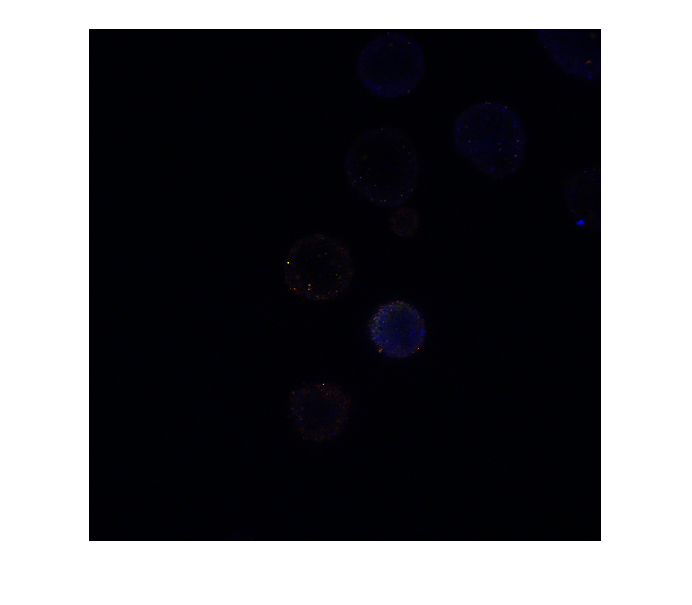

figure
cl.plotRGBcolormap2D([],1,1,1,1:10,9:20,21:30)

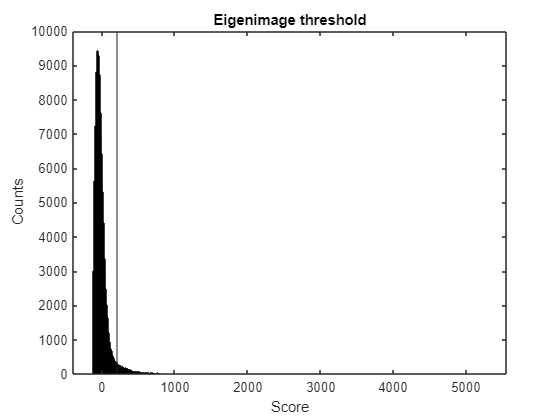

figure
cl.mask.plotThresholdHistogram([],1)

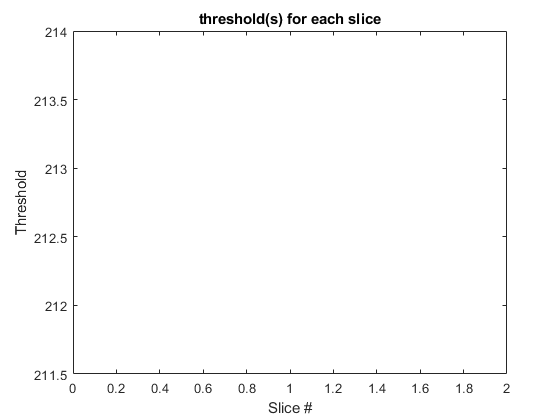


figure
cl.mask.plotThresholdPerZSlice([],1)

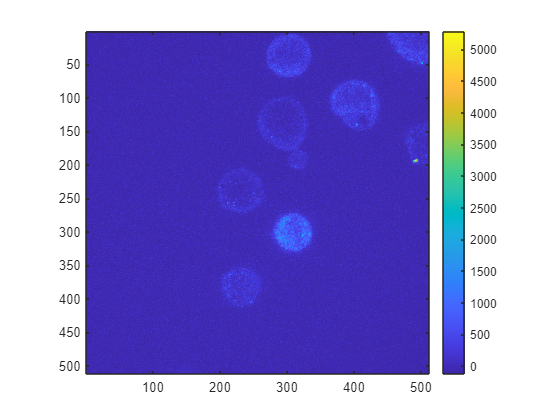


figure
cl.mask.plotEigenImage([],1)

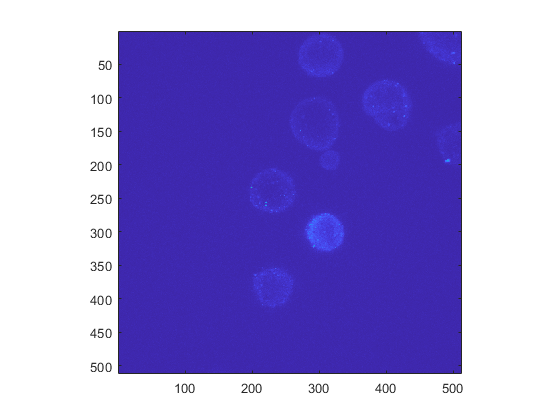

figure
cl.input(1).plotImage

cl = cl.computeMask;

Computed mask without background correction.


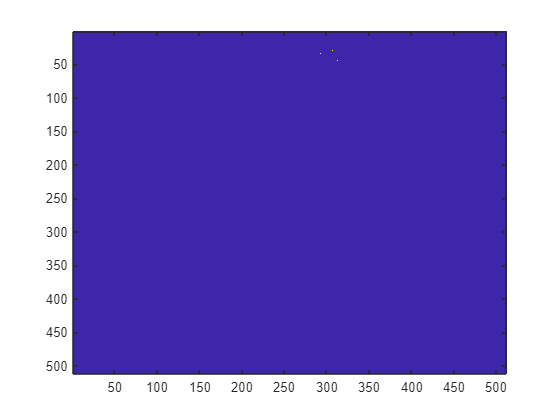

cl = cl.maskSaturatedPixels(10);
cl.maskFlag = true;

figure; imagesc(cl.mask(1).I)

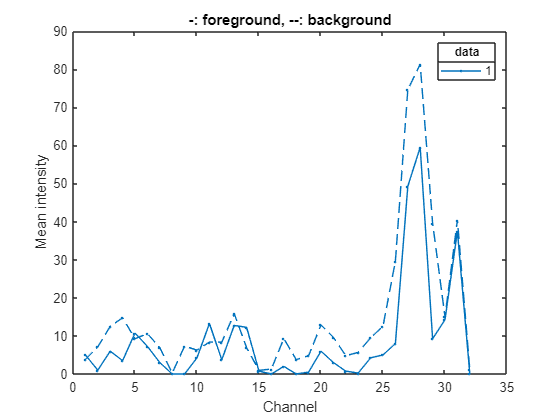


figure
cl.plotChannelsMask([],1)